## Open Loop Step Input Response

### The s-domain tranfer funciton

Single Joint Robotic Arm


$$G(s) = \frac{1}{LMs^3 + s^2LB + s^2RM + sLN + sK_B + sRB + RN)$$


clear; 

% Physical Parameter Definition

J = 3.2284E-6;      % Rotor inertia (kg.m^2)
B_0 = 3.5077E-6;    % coefficient of viscous friction at the joint (Nms)
Kb = 0.0274;        % electromotive force constant (V/rad/sec)
Kt = 0.0274;        % motor torque constant (Nm/Amp)
R = 4;              % armature resistance (ohm)
L = 2.75E-6;        % armature inductance (H)

L_0 = 0.1;      % Link length (m)
m = 0.01;       % mass (kg) of the link
G = 9.8;        % Gravity Coeficient (m/s^2)
M_0 = 0.01;     % Load Mass (kg)
R_0 = 0.025;    % Radius of the Load (m)

M = (J/Kt) + ((m*L_0^2)/(3*Kt)) + ((M_0*L_0^2)/Kt) + ((2*M_0*R_0^2)/(5*Kt))

M = 0.0051

N = ((m*L_0*G) / (2*Kt)) + ((M_0*L_0*G)/Kt)

N = 0.5365

B = B_0/Kt

B = 1.2802e-04

dt = 0.0001;          % sample time 0.1ms
t = 0:dt:10;

s = tf('s');
G = 1 / (s^3*L*M + s^2*L*B + s^2*R*M + s*L*N +s*Kb + s*R*B + R*N)

G =
 
                        1
  ----------------------------------------------
  1.396e-08 s^3 + 0.0203 s^2 + 0.02791 s + 2.146
 
Continuous-time transfer function.
Model Properties


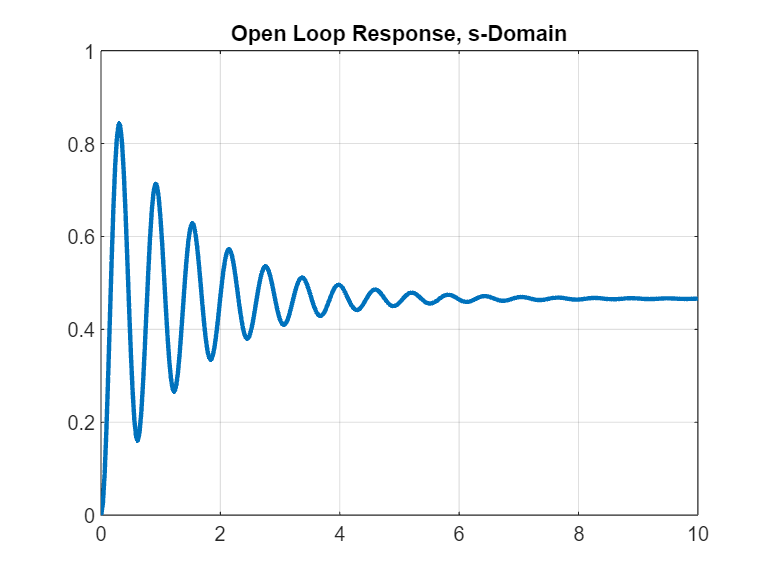


[x, t] = step(G, t);

plot(t, x, 'LineWidth', 2);
title('Open Loop Response, s-Domain')
grid on;

## Convert transfer function to z-domain

Gz = c2d(G, dt, 'tustin')     % convert to z-domain

Gz =
 
  1.215e-07 z^3 + 3.644e-07 z^2 + 3.644e-07 z + 1.215e-07
  -------------------------------------------------------
            z^3 - 1.027 z^2 - 0.9457 z + 0.9727
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


Gz.variable = 'z^-1'            % inverse z-transform

Gz =
 
  1.215e-07 + 3.644e-07 z^-1 + 3.644e-07 z^-2 + 1.215e-07 z^-3
  ------------------------------------------------------------
           1 - 1.027 z^-1 - 0.9457 z^-2 + 0.9727 z^-3
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


[num, den] = tfdata(Gz, 'v')

num = 1.0e-06 *

    0.1215    0.3644    0.3644    0.1215


den =     1.0000   -1.0270   -0.9457    0.9727


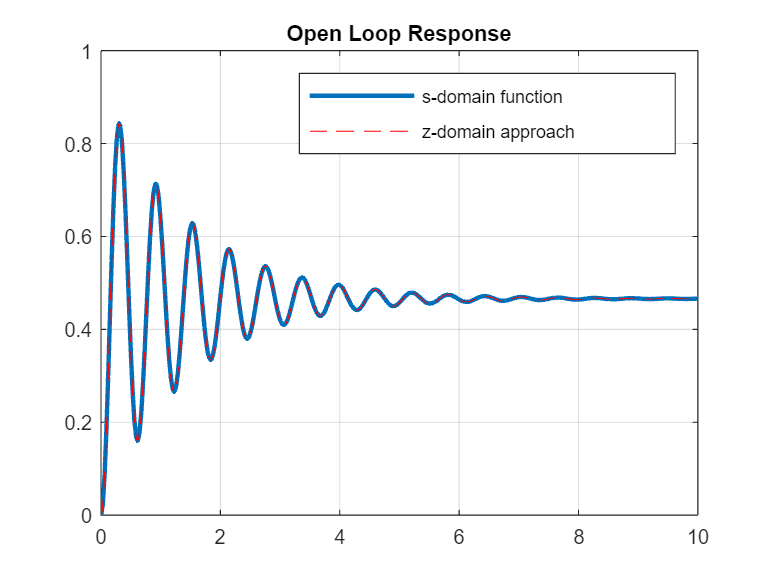

% output variable
y = zeros(size(t));

% step input
u = ones(size(t));
u(1) = 0;

% initial conditions
yk_1 = 0;
yk_2 = 0;
yk_3 = 0;
uk_1 = 0;
uk_2 = 0;
uk_3 = 0;

% solving difference equation
for i = 1:length(t)
    if i == 1
        uterms = num(1)*u(i) + num(2)*uk_1 + num(3)*uk_2 + num(4)*uk_3;
        yterms = -den(2)*yk_1 - den(3)*yk_2 - den(4)*yk_3;
        y(i) = uterms + yterms;
    elseif i == 2
        uterms = num(1)*u(i) + num(2)*u(i-1) + num(3)*uk_1 + num(4)*uk_2;
        yterms = -den(2)*y(i-1) - den(3)*yk_1 - den(4)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 3
        uterms = num(1)*u(i) + num(2)*u(i-1) + num(3)*u(i-2) + num(4)*uk_1;
        yterms = -den(2)*y(i-1) - den(3)*y(i-2) - den(4)*yk_3;
        y(i) = uterms + yterms;
    else
        uterms = num(1)*u(i) + num(2)*u(i-1) + num(3)*u(i-2) + num(4)*u(i-3);
        yterms = -den(2)*y(i-1) - den(3)*y(i-2) - den(4)*y(i-3);
        y(i) = uterms + yterms;
    end
end

hold on;
plot(t, y, 'r--')
legend('s-domain function', 'z-domain approach')
title('Open Loop Response')
grid on;
hold off;

## Closed Loop Step Response

Response with PD Controller 

### The s-domain tranfer funciton

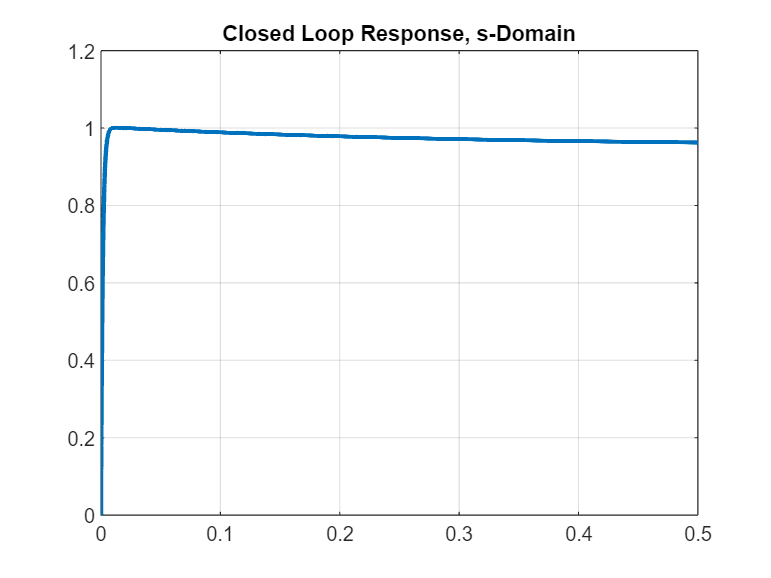

% PD Parameters
kp = 44.5;
kd = 13.4;

C = pid(kp, 0, kd);         % PD Controller

t = 0:dt:0.5;

G_cl = feedback(C*G, 1);     % Closed Loop Transfer Function
[x, t] = step(G_cl, t);      % Step Response of Closed Loop
plot(t, x, 'LineWidth', 2);
title('Closed Loop Response, s-Domain')
grid on;

### Solving difference equation step by step

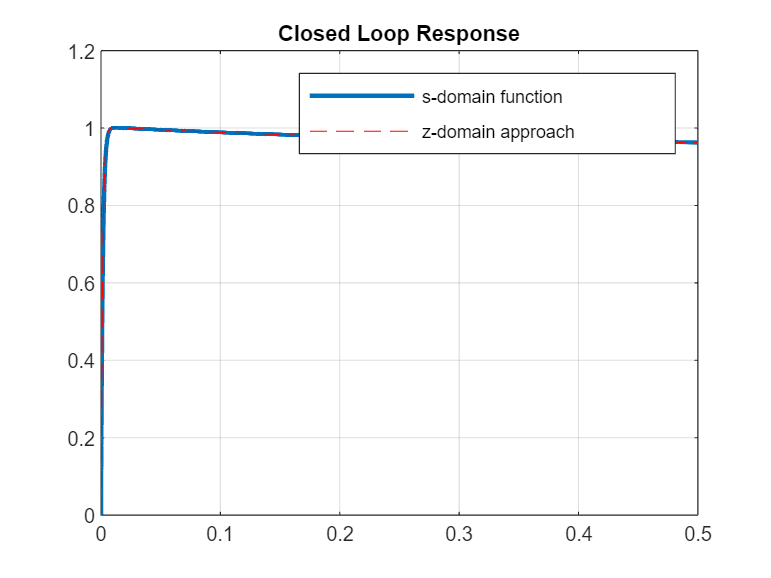

% output variable
y = zeros(size(t));

% Selection of Tracking Signal
S=2;
if S==1
    for k=1:1:length(t)
        u(k) = 0.5*sign(sin(2*2*pi*k*dt)); %Square Signal
    end
elseif S==2
    % step input
    u = ones(size(t));
    u(1) = 0;
end

ek_1 = 0;               % intial value of error
e = zeros(size(t));     % error vector
up = zeros(size(t));    % controller output vector

% solving difference equation
for i = 1:length(t)
    if i == 1
        e(i) = u(i) - yk_1;     % error
        up(i) = kp*e(i) + kd*((e(i) - ek_1)/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*uk_1 + num(3)*uk_2 + num(4)*uk_3;
        yterms = -den(2)*yk_1 - den(3)*yk_2 - den(4)*yk_3;
        y(i) = uterms + yterms;
    elseif i == 2
        e(i) = u(i) - y(i-1);     % error
        up(i) = kp*e(i) + kd*((e(i) - e(i-1))/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*up(i-1) + num(3)*uk_1 + num(4)*uk_2;
        yterms = -den(2)*y(i-1) - den(3)*yk_1 - den(4)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 3
        e(i) = u(i) - y(i-1);     % error
        up(i) = kp*e(i) + kd*((e(i) - e(i-1))/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*up(i-1) + num(3)*up(i-2) + num(4)*uk_1;
        yterms = -den(2)*y(i-1) - den(3)*y(i-2) - den(4)*yk_3;
        y(i) = uterms + yterms;
    else
        e(i) = u(i) - y(i-1);     % error
        up(i) = kp*e(i) + kd*((e(i) - e(i-1))/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*up(i-1) + num(3)*up(i-2) + num(4)*up(i-3);
        yterms = -den(2)*y(i-1) - den(3)*y(i-2) - den(4)*y(i-3);
        y(i) = uterms + yterms;
    end
end


hold on;
plot(t, y, 'r--')
legend('s-domain function', 'z-domain approach')
title('Closed Loop Response')
grid on;
hold off;

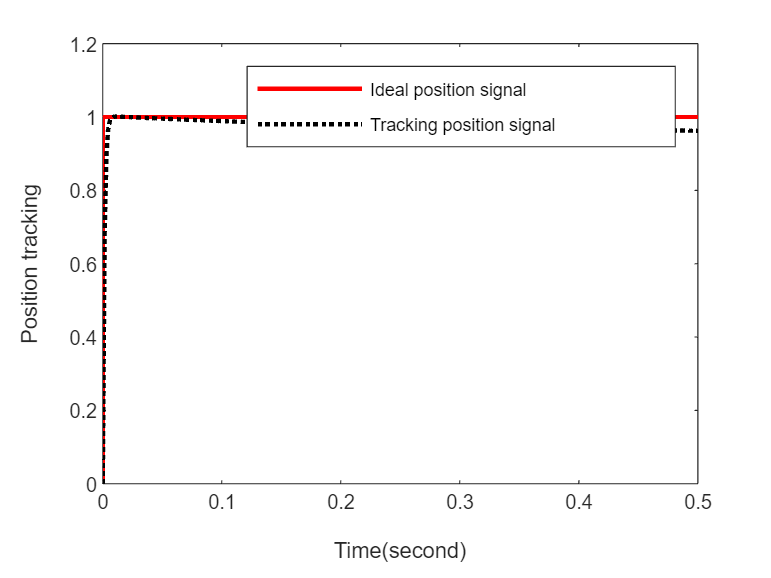


%figure(1);
plot(t,u,'r',t,y,'k:','linewidth',2);
xlabel('Time(second)');ylabel('Position tracking');
legend('Ideal position signal','Tracking position signal');

## References: 

- D. M. Dawson, Carroll, and M. Schneider, “Integrator Backstepping Control of a Brush DC Motor Turning a Robotic Load,” IEEE Trans. Contr. Sys. Tech., vol. 2, no. 3, pp. 233-244, Sept. 1994.

- [4 Ways to Implement a Transfer Function in Code | Control Systems in Practice](https://www.youtube.com/watch?v=nkq4WkX7CFU&t=923s)